## Exam 07/02/2025

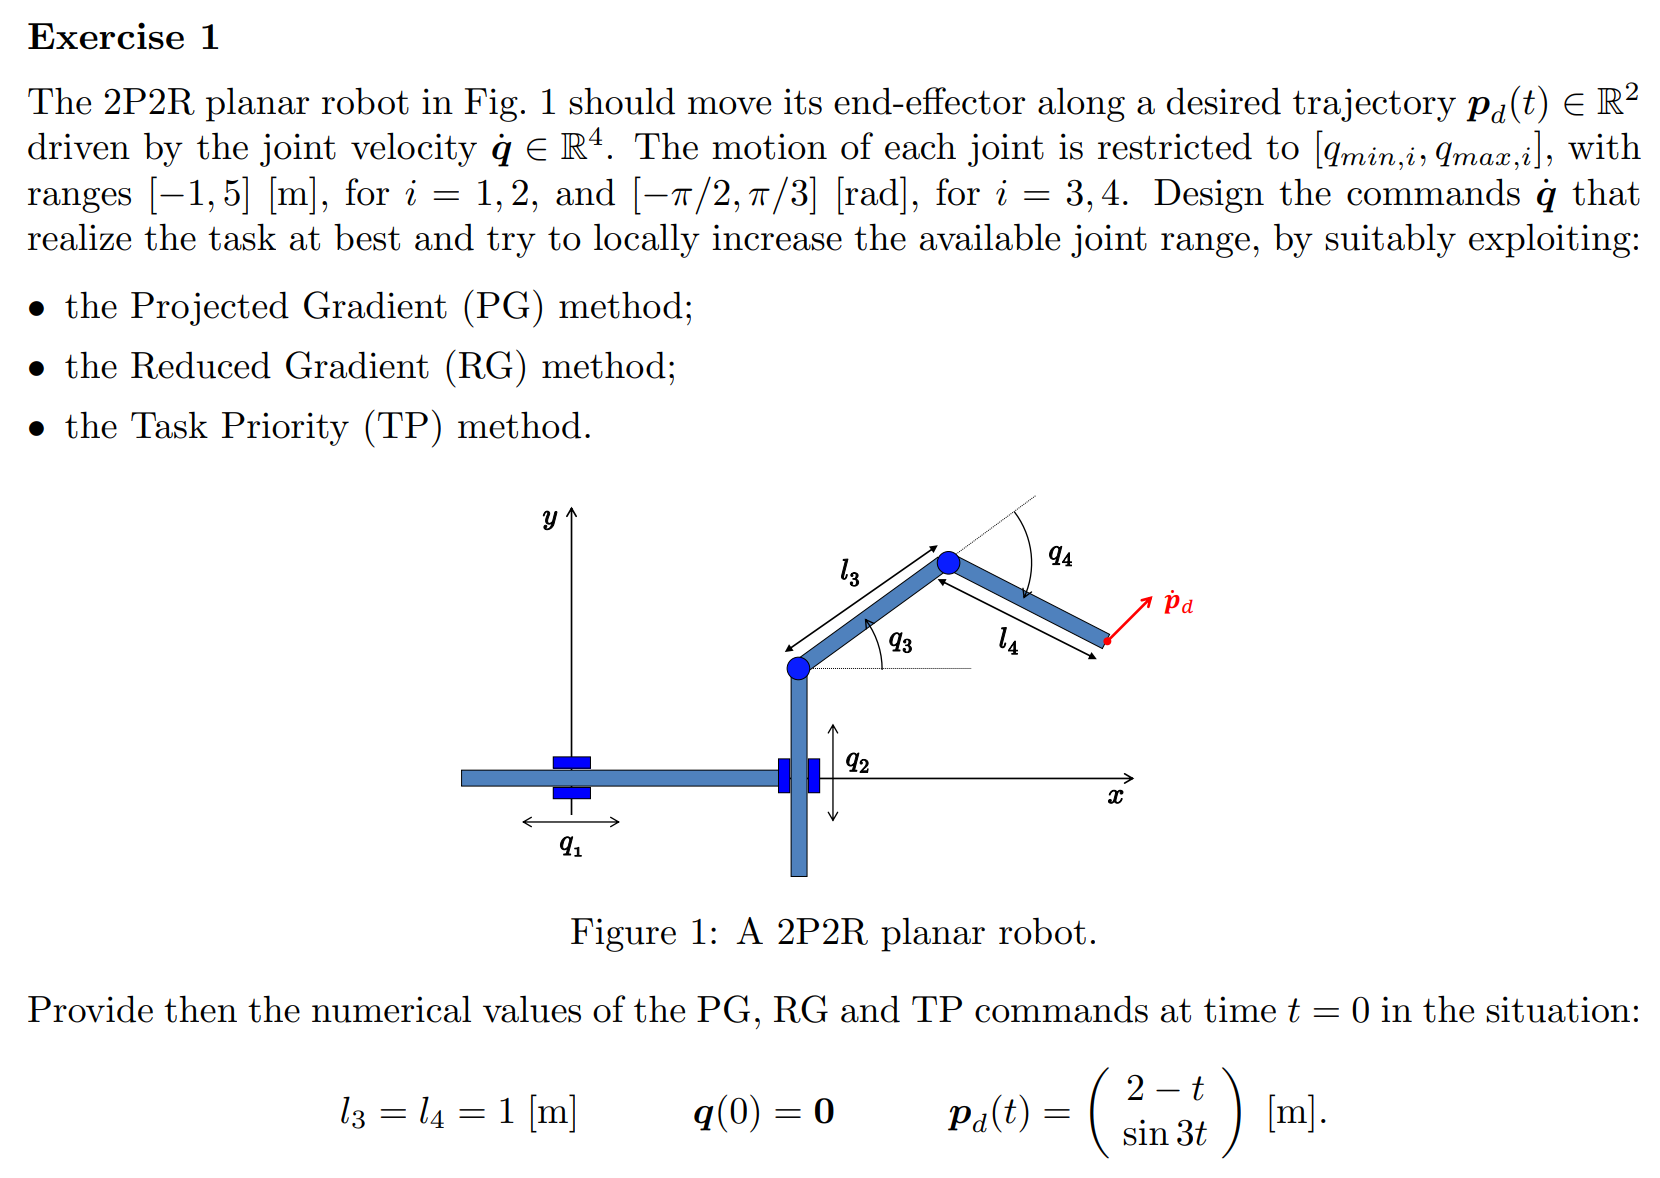

syms q1 q2 q3 q4 l1 l2 l3 l4 t real

p = [q1+l3*cos(q3)+l4*cos(q3+q4);
     q2+l3*sin(q3)+l4*sin(q3+q4);];
J = simplify(jacobian(p,[q1,q2,q3,q4]))

$$J = \left(\begin{array}{cccc} 1 & 0 & -l_{4}\,\sin\left(q_{3}+q_{4}\right)-l_{3}\,\sin\left(q_{3}\right) & -l_{4}\,\sin\left(q_{3}+q_{4}\right)\\ 0 & 1 & l_{4}\,\cos\left(q_{3}+q_{4}\right)+l_{3}\,\cos\left(q_{3}\right) & l_{4}\,\cos\left(q_{3}+q_{4}\right) \end{array}\right)$$


cell_range = {[-1, 5],[-1, 5],[-pi/2, pi/3],[-pi/2, pi/3]};
joint_pos = [q1,q2,q3,q4]

$$joint\_pos = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

H = H_range(joint_pos,cell_range)

$$H = \frac{{\left(q_{1}-2\right)}^{2}}{288}+\frac{{\left(q_{2}-2\right)}^{2}}{288}+\frac{{\left(12\,q_{3}+\pi \right)}^{2}}{800\,\pi^{2}}+\frac{{\left(12\,q_{4}+\pi \right)}^{2}}{800\,\pi^{2}}$$

grad_H =-jacobian(H,joint_pos)

$$grad\_H = \left(\begin{array}{cccc} \frac{1}{72}-\frac{q_{1}}{144} & \frac{1}{72}-\frac{q_{2}}{144} & -\frac{288\,q_{3}+24\,\pi }{800\,\pi^{2}} & -\frac{288\,q_{4}+24\,\pi }{800\,\pi^{2}} \end{array}\right)$$

grad_H_subs = subs(grad_H,[q1,q2,q3,q4],[0,0,0,0])

$$grad\_H\_subs = \left(\begin{array}{cccc} \frac{1}{72} & \frac{1}{72} & -\frac{3}{100\,\pi } & -\frac{3}{100\,\pi } \end{array}\right)$$


J_subs = eval(subs(J,[q1,q2,q3,q4,l3,l4],[0,0,0,0,1,1]))

J_subs =      1     0     0     0
     0     1     2     1


J_pinv_subs = pinv(J_subs)

J_pinv_subs =     1.0000         0
         0    0.1667
         0    0.3333
         0    0.1667



p_d = [2-t; sin(3*t);];
p_d_dot = diff(p_d,t)

$$p\_d\_dot = \left(\begin{array}{c} -1\\ 3\,\cos\left(3\,t\right) \end{array}\right)$$

p_d_dot_subs = subs(p_d_dot,t,0)

$$p\_d\_dot\_subs = \left(\begin{array}{c} -1\\ 3 \end{array}\right)$$


% Projected Gradient
q_dot_PR = eval(J_pinv_subs*p_d_dot_subs+(eye(4)-J_pinv_subs*J_subs)*grad_H_subs.')

q_dot_PR =    -1.0000
    0.5163
    0.9954
    0.4929



% Reduced Gradient
Ja = J_subs(:, 1:2); 
Jb = J_subs(:, 3:4);  

Ja_inv = inv(Ja);     
task_part = [Ja_inv; zeros(2,2)] * p_d_dot_subs;

M1 = [-Ja_inv * Jb; eye(2)];                      
M2 = [- (Ja_inv * Jb).', eye(2)];                 
secondary_part = M1 * (M2 * grad_H_subs.');

q_dot_RG_matrix = eval(task_part + secondary_part)

q_dot_RG_matrix =    -1.0000
    3.0981
   -0.0373
   -0.0234



% Task Priority
J1 = J_subs;               
r1_dot = p_d_dot_subs;     

J1_pinv = J_pinv_subs;
P1 = eye(4) - J1_pinv*J1; 

J2 = eye(4);
r2_dot = grad_H_subs.';    

J2P1 = J2*P1;
J2P1_pinv = pinv(J2P1);    

v1 = J2P1_pinv * (r2_dot - J2*J1_pinv*r1_dot);

q_dot_TP_hierarchical = eval(J1_pinv*r1_dot + P1*v1)

q_dot_TP_hierarchical =    -1.0000
    0.5163
    0.9954
    0.4929



function H = H_range(joint_pos, cell_range)
%Input:
%   joint_pos: symbolic array of joint parameter q
%   cell_range: cell containing the range for the various joints
% Output:
%   H: the "distance" from the mid points of the joint ranges)

        H = 0;
        N = length(joint_pos);
        for i=1:4
            qi = joint_pos(i);
            range =  cell_range{i};
            q_mi = min(range);
            q_Mi = max(range);
            q_hat_i = mean([q_mi, q_Mi]);
            H = simplify(H + 1/(2*N)*((qi - q_hat_i)/(q_Mi-q_mi))^2);
        end
        
end